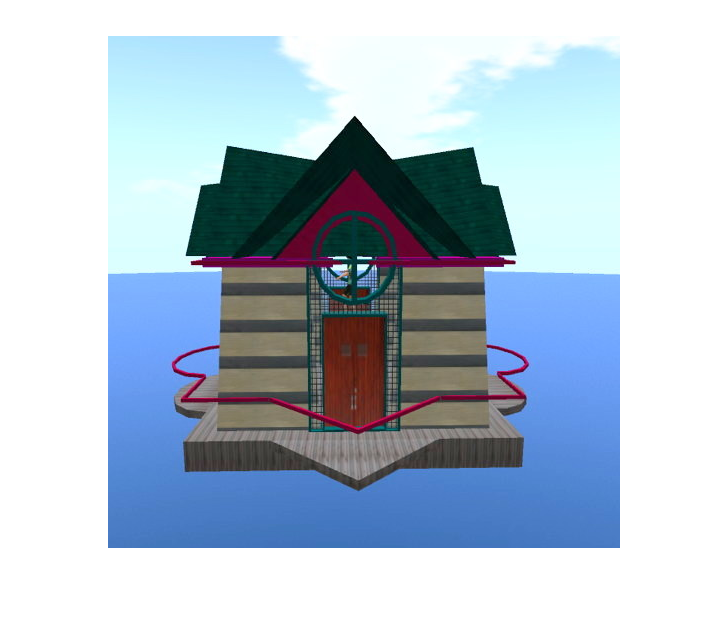

clear all;
clc;

%Input image
img = imread ('Canny/Canny/House.jpg');
%Show input image
figure, imshow(img);

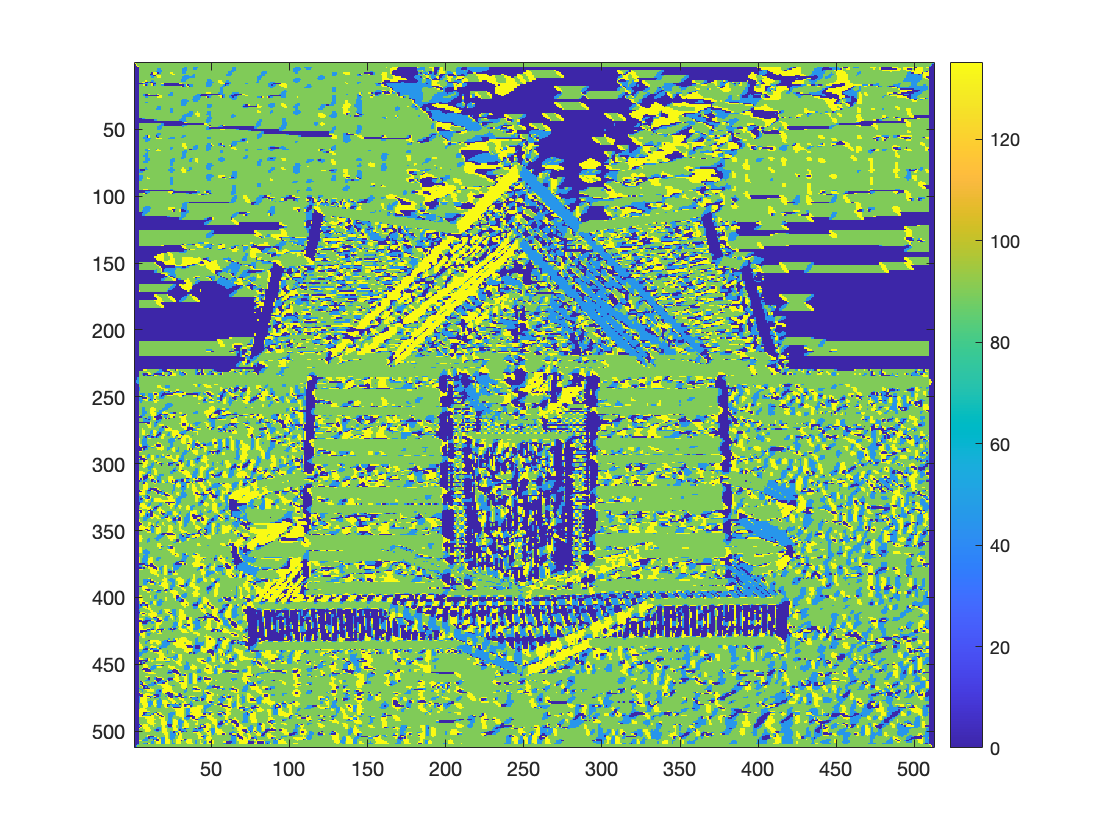

img = rgb2gray(img);
img = double (img);

%Value for Thresholding
T_Low = 0.075;
T_High = 0.175;

%Gaussian Filter Coefficient
B = [2, 4, 5, 4, 2; 4, 9, 12, 9, 4;5, 12, 15, 12, 5;4, 9, 12, 9, 4;2, 4, 5, 4, 2 ];
B = 1/159.* B;

%Convolution of image by Gaussian Coefficient
A=conv2(img, B, 'same');

%Filter for horizontal and vertical direction
KGx = [-1, 0, 1; -2, 0, 2; -1, 0, 1];
KGy = [1, 2, 1; 0, 0, 0; -1, -2, -1];

%Convolution by image by horizontal and vertical filter
Filtered_X = conv2(A, KGx, 'same');
Filtered_Y = conv2(A, KGy, 'same');

%Calculate directions/orientations
arah = atan2 (Filtered_Y, Filtered_X);
arah = arah*180/pi;

pan=size(A,1);
leb=size(A,2);

%Adjustment for negative directions, making all directions positive
for i=1:pan
    for j=1:leb
        if (arah(i,j)<0) 
            arah(i,j)=360+arah(i,j);
        end;
    end;
end;

arah2=zeros(pan, leb);

%Adjusting directions to nearest 0, 45, 90, or 135 degree
for i = 1  : pan
    for j = 1 : leb
        if ((arah(i, j) >= 0 ) && (arah(i, j) < 22.5) || (arah(i, j) >= 157.5) && (arah(i, j) < 202.5) || (arah(i, j) >= 337.5) && (arah(i, j) <= 360))
            arah2(i, j) = 0;
        elseif ((arah(i, j) >= 22.5) && (arah(i, j) < 67.5) || (arah(i, j) >= 202.5) && (arah(i, j) < 247.5))
            arah2(i, j) = 45;
        elseif ((arah(i, j) >= 67.5 && arah(i, j) < 112.5) || (arah(i, j) >= 247.5 && arah(i, j) < 292.5))
            arah2(i, j) = 90;
        elseif ((arah(i, j) >= 112.5 && arah(i, j) < 157.5) || (arah(i, j) >= 292.5 && arah(i, j) < 337.5))
            arah2(i, j) = 135;
        end;
    end;
end;

figure, imagesc(arah2); colorbar;

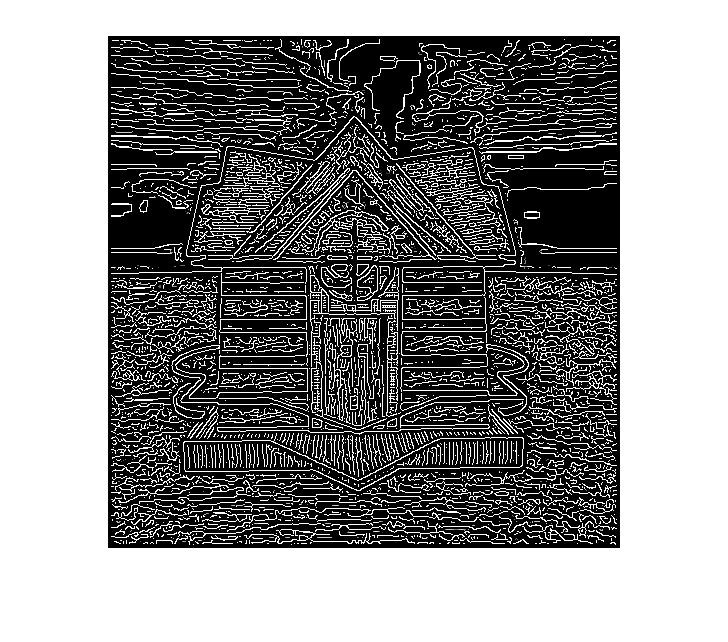


%Calculate magnitude
magnitude = (Filtered_X.^2) + (Filtered_Y.^2);
magnitude2 = sqrt(magnitude);

BW = zeros (pan, leb);

%Non-Maximum Supression
for i=2:pan-1
    for j=2:leb-1
        if (arah2(i,j)==0)
            BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i,j+1), magnitude2(i,j-1)]));
        elseif (arah2(i,j)==45)
            BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i+1,j-1), magnitude2(i-1,j+1)]));
        elseif (arah2(i,j)==90)
            BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i+1,j), magnitude2(i-1,j)]));
        elseif (arah2(i,j)==135)
            BW(i,j) = (magnitude2(i,j) == max([magnitude2(i,j), magnitude2(i+1,j+1), magnitude2(i-1,j-1)]));
        end;
    end;
end;

BW = BW.*magnitude2;
figure, imshow(BW);

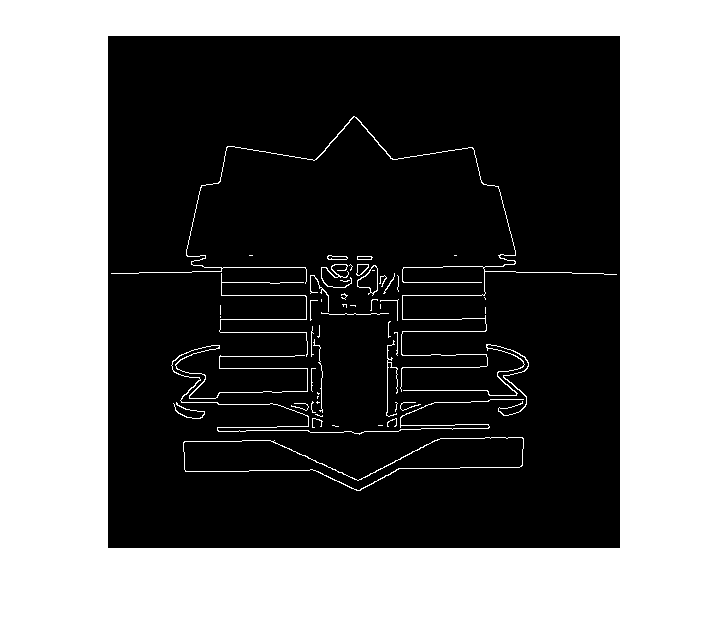


%Hysteresis Thresholding
T_Low = T_Low * max(max(BW));
T_High = T_High * max(max(BW));

T_res = zeros (pan, leb);

for i = 1  : pan
    for j = 1 : leb
        if (BW(i, j) < T_Low)
            T_res(i, j) = 0;
        elseif (BW(i, j) > T_High)
            T_res(i, j) = 1;
        %Using 8-connected components
        elseif ( BW(i+1,j)>T_High || BW(i-1,j)>T_High || BW(i,j+1)>T_High || BW(i,j-1)>T_High || BW(i-1, j-1)>T_High || BW(i-1, j+1)>T_High || BW(i+1, j+1)>T_High || BW(i+1, j-1)>T_High)
            T_res(i,j) = 1;
        end;
    end;
end;

edge_final = uint8(T_res.*255);
%Show final edge detection result
figure, imshow(edge_final);